## Исследование управляемости

function doC(A, B)
    % МАТРИЦА УПРАВЛЯЕМОСТИ %%%%%%%%%%%%%%%%%
    disp('Матрица управляемости');
    Co = ctrb(A, B)
    rank_Co = rank(Co);
    fprintf('Ранг матрицы управляемости: %d\n', rank_Co);
    if rank_Co == size(A, 1)
        fprintf('Система полностью управляемая.\n');
    else
        fprintf('Система не полностью управляемая.\n');
    end
    
    % СОБСТВЕННЫЕ ЧИСЛА И ХАУТУС %%%%%%%%%%%
    eigenvalues = eig(A);
    fprintf('\n\nСобственные числа системы:\n');
    disp(eigenvalues);
    for i = 1:length(eigenvalues)
        fprintf("Матрица Хаутуса для собственного числа %d + %dj\n", real(eigenvalues(i)), imag(eigenvalues(i)));
        Hautus = [A - eigenvalues(i) * eye(size(A)), B]
        rank_Hautus = rank(Hautus);
        fprintf('Ранг матрицы Хаутуса: %d\n', rank_Hautus);
        if rank_Hautus == size(A, 1)
            fprintf('Собственное число управляемо.\n\n');
        else
            fprintf('Собственное число не управляемо.\n\n');
        end
    end
    
    % ЖОРДАН %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [P, J] = jordan(A);

    fprintf('\nКомплексная жорданова форма матрицы A:\n');
    disp(J);

    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица B:');
    disp(P1\B);    
end

function [W_inv] = gramAt(A, B, t)    
    % Определяем функцию для подынтегрального выражения
    gramian_integrand = @(tau) expm(A*tau) * B * B' * expm(A'*tau);
    
    % Вычисляем интеграл численно
    W_c_t = integral(@(tau) gramian_integrand(tau), 0, t, 'ArrayValued', true);
    
    disp('Грамиан управления в точке t = 3:');
    disp(W_c_t);

    if (rank(W_c_t) == size(W_c_t, 1))
        disp('Грамиан управления в точке t = 3 обратный:');
        W_inv = inv(W_c_t);
    else
        disp('Грамиан управления в точке t = 3 всевдо-обратный:');
        W_inv = pinv(W_c_t);
    end
    disp(W_inv);

    ev = eig(W_c_t);
    disp('Его собственные числа:');
    disp(ev);
    
end

function plot_control_and_state(A, B, x1, t1, Gramian_inv, path)
    % Функция для расчета управления и состояния системы и их отображения
    % A, B - матрицы системы x' = Ax + Bu
    % x1 - конечное состояние x(t1)
    % t1 - время достижения состояния x1

    % Шаг времени для моделирования
    dt = 0.01;
    t_vals = 0:dt:t1;

    % Расчет управления
    u_vals = zeros(1, length(t_vals));
    x_vals = zeros(size(A, 1), length(t_vals));

    for k = 1:length(t_vals)
        t = t_vals(k);
        % Управление u(t)
        exp_term = expm(A' * (t1 - t));
        u_vals(k) = B' * exp_term * Gramian_inv * x1;

        % Состояние x(t)
        x_vals(:, k) = expm(A * t) * zeros(size(A, 1), 1) + ...
                       integral(@(tau) expm(A * (t - tau)) * B * ...
                       (B' * expm(A' * (t1 - tau)) * Gramian_inv * x1), 0, t, 'ArrayValued', true);
    end

    % Графики
    figure;
    subplot(2, 1, 1);
    plot(t_vals, u_vals, 'LineWidth', 2);
    grid on;
    xlabel('Время, t');
    ylabel('u(t)');
    title('Управление u(t)');

    subplot(2, 1, 2);
    plot(t_vals, x_vals, 'LineWidth', 2);
    grid on;
    xlabel('Время, t');
    ylabel('Состояния x');
    legend('x1', 'x2', 'x3');
    title('Состояние системы x(t)');

    exportgraphics(gcf, path, 'Resolution', 300);
end


% Данные задачи 1
A = [-1 1 0; -2 -4 -1; 2 2 -1];
B = [2; 3; -1];
x1 = [1; -3; 3];
t1 = 3;

doC(A, B);

Матрица управляемости


Co =      2     1   -16
     3   -15    47
    -1    11   -39


Ранг матрицы управляемости: 3
Система полностью управляемая.


Собственные числа системы:
  -2.0000 + 1.0000i
  -2.0000 - 1.0000i
  -2.0000 + 0.0000i

Матрица Хаутуса для собственного числа -2.000000e+00 + 1j


Hautus =    1.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 - 1.0000i  -1.0000 + 0.0000i   3.0000 + 0.0000i
   2.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 - 1.0000i  -1.0000 + 0.0000i


Ранг матрицы Хаутуса: 3
Собственное число управляемо.

Матрица Хаутуса для собственного числа -2.000000e+00 + -1j


Hautus =    1.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 1.0000i  -1.0000 + 0.0000i   3.0000 + 0.0000i
   2.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 1.0000i  -1.0000 + 0.0000i


Ранг матрицы Хаутуса: 3
Собственное число управляемо.

Матрица Хаутуса для собственного числа -2 + 0j


Hautus =      1     1     0     2
    -2    -2    -1     3
     2     2     1    -1


Ранг матрицы Хаутуса: 3
Собственное число управляемо.


Комплексная жорданова форма матрицы A:
  -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 1.0000i

Вещественная жорданова форма матрицы A:
    -2     0     0
     0    -2    -1
     0     1    -2

Вещественная P:
   -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0

Вещественная P^{-1}:
         0    1.0000    1.0000
         0         0    0.7071
   -1.4142   -1.4142   -0.7071

Новая матрица B:
    2.0000
   -0.7071
   -6.3640



gr = gramAt(A, B, t1);

Грамиан управления в точке t = 3:
    2.2838    0.2838    1.1868
    0.2838    1.1735   -0.7618
    1.1868   -0.7618    1.3500

Грамиан управления в точке t = 3 обратный:
   55.6117  -71.3016  -89.1208
  -71.3016   92.7627  115.0234
  -89.1208  115.0234  143.9898

Его собственные числа:
    0.0034
    3.1144
    1.6894



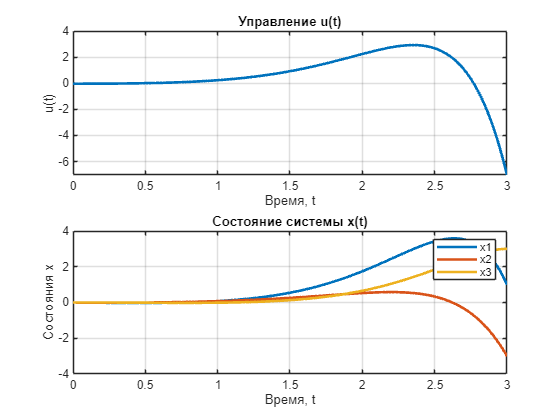

plot_control_and_state(A, B, x1, t1, gr, "figs/task_1.png");

% Transpose of A
A_T = A';

syms t

% Compute exp(A^T * (T - t))
exp_A_T = expm(A_T * (3 - t));

u = B'*exp_A_T/gr*x1

$$u = -\frac{405887719195537212572277707588776299228823552\,{\mathrm{e}}^{2\,t-6}}{19301344161402620295545842144861197749311363}+{\mathrm{e}}^{t\,\left(2-\mathrm{i}\right)-6+3\,\mathrm{i}}\,\left(\frac{66841085104317398875173118567085913155829760}{19301344161402620295545842144861197749311363}-\frac{196265090638186285960380331952845399116480512}{2757334880200374327935120306408742535615909}\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(2+\mathrm{i}\right)-6-3\,\mathrm{i}}\,\left(\frac{66841085104317398875173118567085913155829760}{19301344161402620295545842144861197749311363}+\frac{196265090638186285960380331952845399116480512}{2757334880200374327935120306408742535615909}\,\mathrm{i}\right)$$

var = vpa(u)

$$var = -21.028987193917873144608747843742\,{\mathrm{e}}^{2.0\,t-6.0}+{\mathrm{e}}^{t\,\left(2.0-1.0\,\mathrm{i}\right)-6.0+3.0\,\mathrm{i}}\,\left(3.4630274733912669767638446526682-71.179272437130954178071901134905\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(2.0+1.0\,\mathrm{i}\right)-6.0-3.0\,\mathrm{i}}\,\left(3.4630274733912669767638446526682+71.179272437130954178071901134905\,\mathrm{i}\right)$$

var2 = real(var)

$$var2 = \mathrm{real}\left({\mathrm{e}}^{t\,\left(2.0-1.0\,\mathrm{i}\right)-6.0+3.0\,\mathrm{i}}\,\left(3.4630274733912669767638446526682-71.179272437130954178071901134905\,\mathrm{i}\right)\right)+\mathrm{real}\left({\mathrm{e}}^{t\,\left(2.0+1.0\,\mathrm{i}\right)-6.0-3.0\,\mathrm{i}}\,\left(3.4630274733912669767638446526682+71.179272437130954178071901134905\,\mathrm{i}\right)\right)-21.028987193917873144608747843742\,\mathrm{real}\left({\mathrm{e}}^{2.0\,t-6.0}\right)$$

ua = vpa(u);

% Display the result
disp('Matrix exponential e^{A^T * (T - t)}:');

Matrix exponential e^{A^T * (T - t)}:


disp(exp_A_T);

$$\begin{array}{l} \left(\begin{array}{ccc} \sigma_{2}+\sigma_{3} & \sigma_{4}\,\mathrm{i}-\sigma_{5}\,\mathrm{i} & -\sigma_{4}\,\mathrm{i}+\sigma_{5}\,\mathrm{i}\\ -\sigma_{1}+\sigma_{2}+\sigma_{3} & \sigma_{1}+\sigma_{4}\,\mathrm{i}-\sigma_{5}\,\mathrm{i} & -\sigma_{4}\,\mathrm{i}+\sigma_{5}\,\mathrm{i}\\ -\sigma_{1}+\frac{\sigma_{4}}{2}+\frac{\sigma_{5}}{2} & \sigma_{1}+\sigma_{4}\,\left(-\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)+\sigma_{5}\,\left(-\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right) & \sigma_{2}+\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,t-6}\\ \sigma_{2}=\sigma_{4}\,\left(\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)\\ \sigma_{3}=\sigma_{5}\,\left(\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)\\ \sigma_{4}={\mathrm{e}}^{t\,\left(2-\mathrm{i}\right)-6+3\,\mathrm{i}}\\ \sigma_{5}={\mathrm{e}}^{t\,\left(2+\mathrm{i}\right)-6-3\,\mathrm{i}} \end{array}$$

% Данные задачи 2
A = [-1 1 0; -2 -4 -1; 2 2 -1];
B = [2; -1; 1];
x1 = [1; -3; 3];
t1 = 3;

doC(A, B);

Матрица управляемости


gr = gramAt(A, B, t1);
plot_control_and_state(A, B, x1, t1, gr, "figs/task_2.png");

## Исследование наблюдаемости

function doN(A, C)
    % МАТРИЦА НАБЛЮДАЕМОСТИ %%%%%%%%%%%%%%%%%
    disp('Матрица наблюдаемости');
    Ob = obsv(A, C)
    rank_Ob = rank(Ob);
    fprintf('Ранг матрицы наблюдаемости: %d\n', rank_Ob);
    if rank_Ob == size(A, 1)
        fprintf('Система полностью наблюдаема.\n');
    else
        fprintf('Система не полностью наблюдаема.\n');
    end
    disp('Basis for the nullspace of V:');
    disp(null(Ob));

    
    % СОБСТВЕННЫЕ ЧИСЛА И ХАУТУС %%%%%%%%%%%
    fprintf('\n\nСобственные числа системы:\n');
    eigenvalues = eig(A)
    for i = 1:length(eigenvalues)
        fprintf("Матрица Хаутуса для собственного числа %d + %dj\n", real(eigenvalues(i)), imag(eigenvalues(i)));
        Hautus = [A - eigenvalues(i) * eye(size(A)); C]
        rank_Hautus = rank(Hautus);
        fprintf('Ранг матрицы Хаутуса: %d\n', rank_Hautus);
        if rank_Hautus == size(A, 1)
            fprintf('Собственное число управляемо.\n\n');
        else
            fprintf('Собственное число не управляемо.\n\n');
        end
    end
    
    % ЖОРДАН %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [P, J] = jordan(A);

    fprintf('\nКомплексная жорданова форма матрицы A:\n');
    disp(J);

    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица C:');
    disp(C*P1);    
end

function [W_inv] = ObGramAt(A, C, t)    
    % Определяем функцию для подынтегрального выражения
    gramian_integrand = @(tau) expm(A'*tau) * C' * C * expm(A*tau);
    
    % Вычисляем интеграл численно
    W_c_t = integral(@(tau) gramian_integrand(tau), 0, t, 'ArrayValued', true);
    
    disp('Грамиан наблюдения в точке t = 3:');
    disp(W_c_t);

    if (rank(W_c_t) == size(W_c_t, 1))
        disp('Грамиан наблюдения в точке t = 3 обратный:');
        W_inv = inv(W_c_t);
    else
        disp('Грамиан наблюдения в точке t = 3 всевдо-обратный:');
        W_inv = pinv(W_c_t);
    end
    disp(W_inv);

    ev = eig(W_c_t);
    disp('Его собственные числа:');
    disp(ev);
end

function find_initial_conditions_and_plot(A, C, Q_inv, f_func, t1, path)
    % Функция для нахождения начальных условий и моделирования системы
    % A, C - матрицы системы x' = Ax, y = Cx
    % Q_inv - обратный Грамиан наблюдаемости в момент времени t1
    % f_func - функция сигнала f(t), заданная как function handle
    % t1 - конечное время интегрирования
    % path - путь для сохранения графиков

    % Шаг времени для моделирования
    dt = 0.01;
    t_vals = 0:dt:t1;

    % Расчет интеграла для вычисления начальных условий
    integrand = @(t) expm(A' * t) * C' * f_func(t);
    integral_result = integral(@(t) integrand(t), 0, t1, 'ArrayValued', true);

    % Вычисление начальных условий x(0)
    x0 = Q_inv * integral_result;
    disp('Начальные условия x(0):');
    disp(x0);

    % Моделирование системы
    x_vals = zeros(size(A, 1), length(t_vals));
    y_vals = zeros(1, length(t_vals));
    f_vals = arrayfun(f_func, t_vals); % Значения f(t) на интервале

    for k = 1:length(t_vals)
        t = t_vals(k);
        x_vals(:, k) = expm(A * t) * x0;
        y_vals(k) = C * x_vals(:, k);
    end

    % Расчет ошибки e(t)
    e_vals = y_vals - f_vals;

    % Построение графиков
    figure;
    % График выхода системы y(t) и сигнала f(t)
    subplot(2, 1, 1);
    plot(t_vals, y_vals, 'b', 'LineWidth', 2, 'DisplayName', 'y(t)'); hold on;
    plot(t_vals, f_vals, 'r--', 'LineWidth', 2, 'DisplayName', 'f(t)');
    grid on;
    xlabel('Время, t');
    ylabel('Выход');
    legend('show');
    title('Выход системы y(t) и сигнал f(t)');

    % График ошибки e(t)
    subplot(2, 1, 2);
    plot(t_vals, e_vals, 'k', 'LineWidth', 2);
    grid on;
    xlabel('Время, t');
    ylabel('Ошибка e(t)');
    title('Ошибка e(t) = y(t) - f(t)');

    % Сохранение графиков
    exportgraphics(gcf, path, 'Resolution', 300);
end

function find_initial_conditions_and_plot_3(A, C, Q_inv, f_func, t1, path)
    % Функция для нахождения начальных условий и моделирования системы
    % A, C - матрицы системы x' = Ax, y = Cx
    % Q_inv - обратный Грамиан наблюдаемости в момент времени t1
    % f_func - функция сигнала f(t), заданная как function handle
    % t1 - конечное время интегрирования
    % path - путь для сохранения графиков

    % Шаг времени для моделирования
    dt = 0.01;
    t_vals = 0:dt:t1;

    % Расчет интеграла для вычисления начальных условий
    integrand = @(t) expm(A' * t) * C' * f_func(t);
    integral_result = integral(@(t) integrand(t), 0, t1, 'ArrayValued', true);

    % Вычисление начальных условий x(0)
    x0 = Q_inv * integral_result;
    core = null(obsv(A, C));

    disp('Начальные условия 1:');
    x01 = x0 + core;
    disp(x01);

    disp('Начальные условия 2:');
    x02 = x0 + core * 2;
    disp(x02);

    disp('Начальные условия 3:');
    x03 = x0 + core * 8;
    disp(x03);

    % Моделирование системы для каждого набора начальных условий
    x_vals1 = zeros(size(A, 1), length(t_vals));
    x_vals2 = zeros(size(A, 1), length(t_vals));
    x_vals3 = zeros(size(A, 1), length(t_vals));
    y_vals1 = zeros(1, length(t_vals));
    y_vals2 = zeros(1, length(t_vals));
    y_vals3 = zeros(1, length(t_vals));
    f_vals = arrayfun(f_func, t_vals); % Значения f(t) на интервале

    for k = 1:length(t_vals)
        t = t_vals(k);
        x_vals1(:, k) = expm(A * t) * x01;
        y_vals1(k) = C * x_vals1(:, k);

        x_vals2(:, k) = expm(A * t) * x02;
        y_vals2(k) = C * x_vals2(:, k);

        x_vals3(:, k) = expm(A * t) * x03;
        y_vals3(k) = C * x_vals3(:, k);
    end

    figure('Position', [0 0 800 1100]);
    % График выхода системы y(t) и сигнала f(t) для всех начальных условий
    subplot(4, 1, 1);
    plot(t_vals, y_vals1, 'b-', 'LineWidth', 2, 'DisplayName', 'y(t) для x_1'); hold on;
    plot(t_vals, y_vals2, 'g--', 'LineWidth', 2, 'DisplayName', 'y(t) для x_2');
    plot(t_vals, y_vals3, 'm-.', 'LineWidth', 2, 'DisplayName', 'y(t) для x_3');
    plot(t_vals, f_vals, 'r:', 'LineWidth', 2, 'DisplayName', 'f(t)');
    grid on;
    xlabel('Время, t');
    ylabel('Выход');
    legend('show');
    title('Выход системы y(t) и сигнал f(t)');

    % График состояний системы для первого начального условия
    subplot(4, 1, 2);
    plot(t_vals, x_vals1(1, :), 'b-', 'LineWidth', 2, 'DisplayName', 'x_1(t) для x_1'); hold on;
    if size(A, 1) > 1
        plot(t_vals, x_vals1(2, :), 'g--', 'LineWidth', 2, 'DisplayName', 'x_2(t) для x_1');
    end
    if size(A, 1) > 2
        plot(t_vals, x_vals1(3, :), 'm-.', 'LineWidth', 2, 'DisplayName', 'x_3(t) для x_1');
    end
    grid on;
    xlabel('Время, t');
    ylabel('Состояния');
    legend('show');
    title('Состояния системы x(t) для x_1');

    % График состояний системы для второго начального условия
    subplot(4, 1, 3);
    plot(t_vals, x_vals2(1, :), 'b-', 'LineWidth', 2, 'DisplayName', 'x_1(t) для x_2'); hold on;
    if size(A, 1) > 1
        plot(t_vals, x_vals2(2, :), 'g--', 'LineWidth', 2, 'DisplayName', 'x_2(t) для x_2');
    end
    if size(A, 1) > 2
        plot(t_vals, x_vals2(3, :), 'm-.', 'LineWidth', 2, 'DisplayName', 'x_3(t) для x_2');
    end
    grid on;
    xlabel('Время, t');
    ylabel('Состояния');
    legend('show');
    title('Состояния системы x(t) для x_2');

    % График состояний системы для третьего начального условия
    subplot(4, 1, 4);
    plot(t_vals, x_vals3(1, :), 'b-', 'LineWidth', 2, 'DisplayName', 'x_1(t) для x_3'); hold on;
    if size(A, 1) > 1
        plot(t_vals, x_vals3(2, :), 'g--', 'LineWidth', 2, 'DisplayName', 'x_2(t) для x_3');
    end
    if size(A, 1) > 2
        plot(t_vals, x_vals3(3, :), 'm-.', 'LineWidth', 2, 'DisplayName', 'x_3(t) для x_3');
    end
    grid on;
    xlabel('Время, t');
    ylabel('Состояния');
    legend('show');
    title('Состояния системы x(t) для x_3');

    % Сохранение графиков
    exportgraphics(gcf, path, 'Resolution', 500);
end


A = [-21 -38 6; 8 13 -4; -6 -14 -1];
C = [9 18 -2];
t1 = 3;
f = @(t) 3*exp(-5*t) * cos(2*t) - exp(-5*t)*sin(2*t);

doN(A, C);

Матрица наблюдаемости


Ob =      9    18    -2
   -33   -80   -16
   149   438   138


Ранг матрицы наблюдаемости: 3
Система полностью наблюдаема.
Basis for the nullspace of V:


Собственные числа системы:


eigenvalues =    1.0000 + 0.0000i
  -5.0000 + 2.0000i
  -5.0000 - 2.0000i


Матрица Хаутуса для собственного числа 1.000000e+00 + 0j


Hautus =   -22.0000  -38.0000    6.0000
    8.0000   12.0000   -4.0000
   -6.0000  -14.0000   -2.0000
    9.0000   18.0000   -2.0000


Ранг матрицы Хаутуса: 3
Собственное число управляемо.

Матрица Хаутуса для собственного числа -5.000000e+00 + 2.000000e+00j


Hautus =  -16.0000 - 2.0000i -38.0000 + 0.0000i   6.0000 + 0.0000i
   8.0000 + 0.0000i  18.0000 - 2.0000i  -4.0000 + 0.0000i
  -6.0000 + 0.0000i -14.0000 + 0.0000i   4.0000 - 2.0000i
   9.0000 + 0.0000i  18.0000 + 0.0000i  -2.0000 + 0.0000i


Ранг матрицы Хаутуса: 3
Собственное число управляемо.

Матрица Хаутуса для собственного числа -5.000000e+00 + -2.000000e+00j


Hautus =  -16.0000 + 2.0000i -38.0000 + 0.0000i   6.0000 + 0.0000i
   8.0000 + 0.0000i  18.0000 + 2.0000i  -4.0000 + 0.0000i
  -6.0000 + 0.0000i -14.0000 + 0.0000i   4.0000 + 2.0000i
   9.0000 + 0.0000i  18.0000 + 0.0000i  -2.0000 + 0.0000i


Ранг матрицы Хаутуса: 3
Собственное число управляемо.


Комплексная жорданова форма матрицы A:
   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -5.0000 - 2.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -5.0000 + 2.0000i

Вещественная жорданова форма матрицы A:
     1     0     0
     0    -5    -2
     0     2    -5

Вещественная P:
    2.0000    4.2426   -2.8284
   -1.0000   -1.4142    1.4142
    1.0000    1.4142         0

Вещественная P^{-1}:
   -1.0000   -2.0000    1.0000
    0.7071    1.4142         0
         0    0.7071    0.7071

Новая матрица C:
   -2.0000    9.8995         0



grinv = ObGramAt(A, C, t1);

Грамиан наблюдения в точке t = 3:
   1.0e+03 *

    0.8150    1.6278   -0.8099
    1.6278    3.2514   -1.6181
   -0.8099   -1.6181    0.8080

Грамиан наблюдения в точке t = 3 обратный:
   13.6169   -7.2186   -0.8066
   -7.2186    3.9164    0.6073
   -0.8066    0.6073    0.4088

Его собственные числа:
   1.0e+03 *

    4.8720
    0.0001
    0.0024



Начальные условия x(0):
    1.0000
   -0.2857
    0.4286



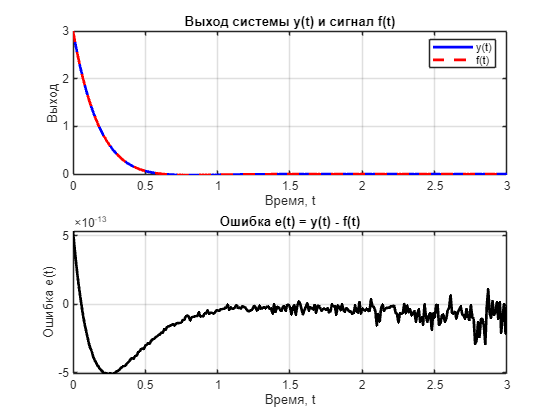

find_initial_conditions_and_plot(A, C, grinv, f, t1, "figs/task_3.png");

A = [-21 -38 6; 8 13 -4; -6 -14 -1];
C = [7 14 0];
t1 = 3;
f = @(t) 3*exp(-5*t) * cos(2*t) - exp(-5*t)*sin(2*t);

doN(A, C);

Матрица наблюдаемости


Ob =      7    14     0
   -35   -84   -14
   147   434   140


Ранг матрицы наблюдаемости: 2
Система не полностью наблюдаема.
Basis for the nullspace of V:
    0.8165
   -0.4082
    0.4082



Собственные числа системы:


eigenvalues =    1.0000 + 0.0000i
  -5.0000 + 2.0000i
  -5.0000 - 2.0000i


Матрица Хаутуса для собственного числа 1.000000e+00 + 0j


Hautus =   -22.0000  -38.0000    6.0000
    8.0000   12.0000   -4.0000
   -6.0000  -14.0000   -2.0000
    7.0000   14.0000         0


Ранг матрицы Хаутуса: 2
Собственное число не управляемо.

Матрица Хаутуса для собственного числа -5.000000e+00 + 2.000000e+00j


Hautus =  -16.0000 - 2.0000i -38.0000 + 0.0000i   6.0000 + 0.0000i
   8.0000 + 0.0000i  18.0000 - 2.0000i  -4.0000 + 0.0000i
  -6.0000 + 0.0000i -14.0000 + 0.0000i   4.0000 - 2.0000i
   7.0000 + 0.0000i  14.0000 + 0.0000i   0.0000 + 0.0000i


Ранг матрицы Хаутуса: 3
Собственное число управляемо.

Матрица Хаутуса для собственного числа -5.000000e+00 + -2.000000e+00j


Hautus =  -16.0000 + 2.0000i -38.0000 + 0.0000i   6.0000 + 0.0000i
   8.0000 + 0.0000i  18.0000 + 2.0000i  -4.0000 + 0.0000i
  -6.0000 + 0.0000i -14.0000 + 0.0000i   4.0000 + 2.0000i
   7.0000 + 0.0000i  14.0000 + 0.0000i   0.0000 + 0.0000i


Ранг матрицы Хаутуса: 3
Собственное число управляемо.


Комплексная жорданова форма матрицы A:
   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -5.0000 - 2.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -5.0000 + 2.0000i

Вещественная жорданова форма матрицы A:
     1     0     0
     0    -5    -2
     0     2    -5

Вещественная P:
    2.0000    4.2426   -2.8284
   -1.0000   -1.4142    1.4142
    1.0000    1.4142         0

Вещественная P^{-1}:
   -1.0000   -2.0000    1.0000
    0.7071    1.4142         0
         0    0.7071    0.7071

Новая матрица C:
         0    9.8995         0



grinv = ObGramAt(A, C, t1);

Грамиан наблюдения в точке t = 3:
    4.5621    8.2793   -0.8448
    8.2793   15.2069   -1.3517
   -0.8448   -1.3517    0.3379

Грамиан наблюдения в точке t = 3 всевдо-обратный:
    0.4308   -0.3175   -1.1791
   -0.3175    0.3118    0.9467
   -1.1791    0.9467    3.3050

Его собственные числа:
   19.8567
    0.0000
    0.2502



Начальные условия 1:
    0.9117
   -0.2416
    0.3844

Начальные условия 2:
    1.7282
   -0.6498
    0.7927

Начальные условия 3:
    6.6272
   -3.0993
    3.2422



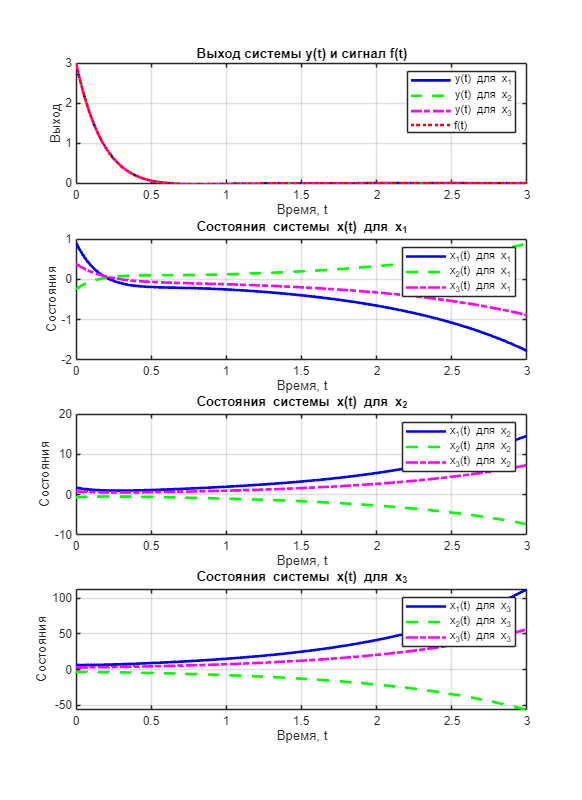

find_initial_conditions_and_plot_3(A, C, grinv, f, t1, "figs/task_41.png");

## Исследование управляемости по выходу

function analyze_system_controllability(A, B, C)
    % Функция для анализа системы по заданию 5
    % A, B, C, D - матрицы системы

    %% Шаг 1: Жорданова (или диагональная) форма
    disp('1. Жорданова (или диагональная) форма системы');
    [P, J] = jordan(A);
    fprintf('\nКомплексная жорданова форма матрицы A:\n');
    disp(J);
    [P1, J1] = cdf2rdf(P, J);
    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);
    disp('Вещественная P:');
    disp(P1);
    disp('Вещественная P^{-1}:');
    disp(inv(P1));
    disp('Новая матрица C:');
    disp(C*P1);
    disp('Новая матрица B:');
    disp(P1\B);

    %% Шаг 2: Определение управляемости и наблюдаемости
    disp('2. Управляемость и наблюдаемость системы');
    
    disp('Матрица управлемочти');
    U = ctrb(A, B)
    disp('Матрица наблюдаемости');
    V = obsv(A, C)
    
    rank_ctrb = rank(U);
    rank_obsv = rank(V);

    disp(['Ранг матрицы управляемости: ', num2str(rank_ctrb)]);
    disp(['Ранг матрицы наблюдаемости: ', num2str(rank_obsv)]);

    if rank_ctrb == size(A, 1)
        disp('Система полностью управляемая.');
    else
        disp('Система не полностью управляемая.');
    end

    if rank_obsv == size(A, 1)
        disp('Система полностью наблюдаемая.');
    else
        disp('Система не полностью наблюдаемая.');
    end

    %% Шаг 3: Матрица управляемости по выходу при D = 0
    disp('3. Матрица управляемости по выходу');
    D = zeros(2, 2);
    U_out = [C * U, D];
    rank_output_ctrb = rank(U_out);

    disp('Матрица управляемости по выходу:');
    disp(U_out);
    disp(['Ранг матрицы управляемости по выходу: ', num2str(rank_output_ctrb)]);

    if rank_output_ctrb == size(C, 1)
        disp('Система полностью управляемая по выходу.');
    else
        disp('Система не полностью управляемая по выходу.');
    end
end

A = [-1 1 0; -2 -4 -1; 2 2 -1];
B = [2; 3; 1];
C = [0 -1 -2; 0 1 2];

analyze_system_controllability(A, B, C);

1. Жорданова (или диагональная) форма системы

Комплексная жорданова форма матрицы A:
  -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 1.0000i

Вещественная жорданова форма матрицы A:
    -2     0     0
     0    -2    -1
     0     1    -2

Вещественная P:
   -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0

Вещественная P^{-1}:
         0    1.0000    1.0000
         0         0    0.7071
   -1.4142   -1.4142   -0.7071

Новая матрица C:
   -1.0000   -1.4142         0
    1.0000    1.4142         0

Новая матрица B:
    4.0000
    0.7071
   -7.7782

2. Управляемость и наблюдаемость системы
Матрица управлемочти


U =      2     1   -18
     3   -17    57
     1     9   -41


Матрица наблюдаемости


V =      0    -1    -2
     0     1     2
    -2     0     3
     2     0    -3
     8     4    -3
    -8    -4     3


Ранг матрицы управляемости: 3
Ранг матрицы наблюдаемости: 3
Система полностью управляемая.
Система полностью наблюдаемая.
3. Матрица управляемости по выходу
Матрица управляемости по выходу:
    -5    -1    25     0     0
     5     1   -25     0     0

Ранг матрицы управляемости по выходу: 1
Система не полностью управляемая по выходу.


## Вычисления управления

% Define matrices and parameters
A = [-1 -2  2;
      1 -4  2;
      0 -1 -1];
B = [2 3 -1];
C_inv = inv([2.2838  0.2838  1.1868;
         0.2838  1.1735 -0.7618;
         1.1868 -0.7618  1.3500]);
v = [1; -3; 3];
t = sym('t', 'real'); % Symbolic variable for time

% Compute intermediate matrices
exponentialMatrix = expm(A * (3 - t)); % Exponential matrix

% Compute overall expression
result = B * exponentialMatrix * C_inv * v;

% Simplify and display the final result
result = simplify(result);
disp('Final Expression:');

Final Expression:


disp(result);

$$-\frac{{\mathrm{e}}^{2\,t-6}\,\left(2215629447570741\,\sin\left(t-3\right)-449630496707900\,\cos\left(t-3\right)+944562334414014\right)}{70368744177664}$$

% Define matrices and parameters
A = [-1  1  0;
     -2 -4 -1;
      2  2 -1];
B = [2 -1  1];
P = [ 9.6001  5.6001 -5.6001;
      5.6001  3.6000 -3.6000;
     -5.6001 -3.6000  3.6000];
x1 = [1; -3; 3];
t = sym('t', 'real'); % Symbolic variable for time

% Compute intermediate matrices
exponentialMatrix = expm(A' * (3 - t)); % Exponential matrix

% Compute overall expression
result = B * exponentialMatrix * P * x1;

% Simplify and display the final result
result = simplify(result);
disp('Final Expression:');

Final Expression:


disp(result);

$$-\frac{{\mathrm{e}}^{2\,t-6}\,\left(160012\,\cos\left(t-3\right)+719989\,\sin\left(t-3\right)\right)}{10000}$$